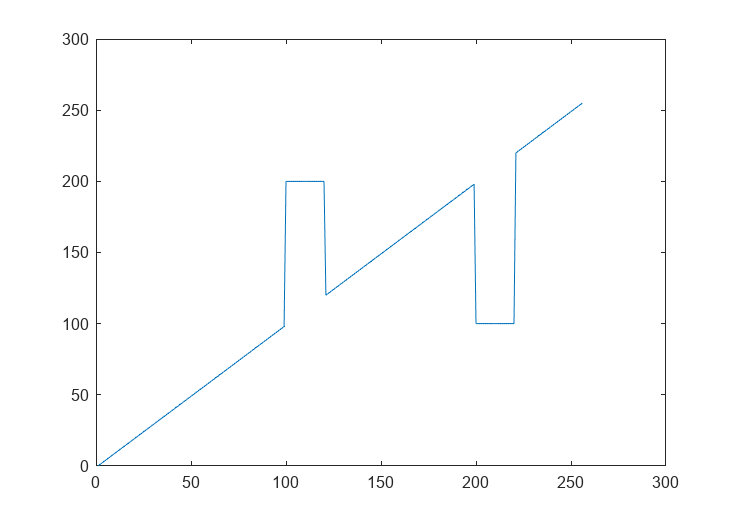

a = imread("bosque.jpg");
lutbase = 0:255;
lutgamma2  = uint8(((lutbase/255).^2)*255);
lutgamma3  = uint8(((lutbase/255).^3)*255);
lutgamma05  = uint8(((lutbase/255).^0.5)*255);
lutgamma03  = uint8(((lutbase/255).^0.3)*255);
lutespec1 = 0:255;
lutespec1(100:120) = 200;
lutespec1(200:220) = 100;
lutespec1 = uint8(lutespec1);
plot(lutespec1);

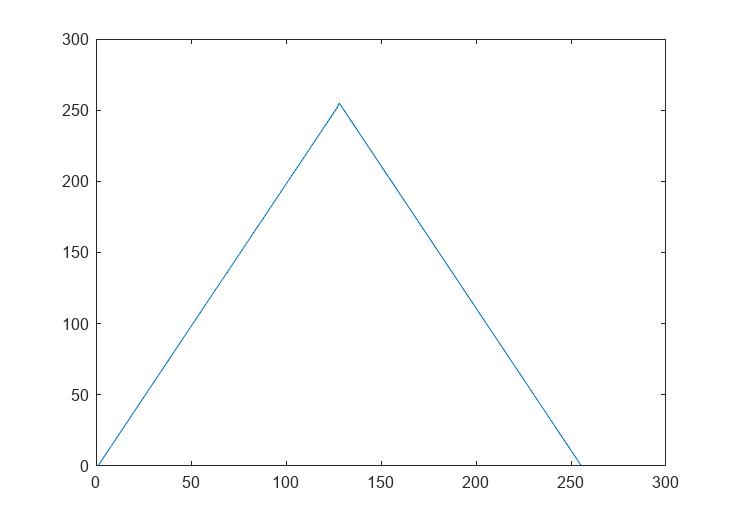


lutespec2 = (0:255)*2;
lutespec2(128:256) = 255-lutespec2(1:129);
lutespec2 = uint8(lutespec2);
plot(lutespec2);

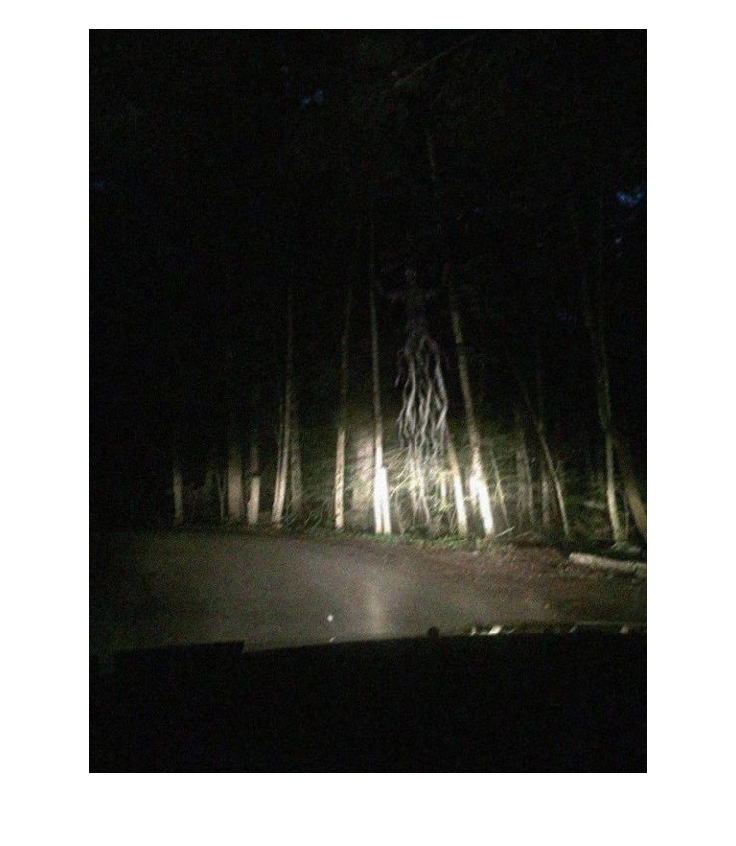



lutinvert = uint8(255-lutbase);

b = lutespec2(a + 1);
%b = lutinvert(a + 1); ohhh

figure(1); imshow(a);

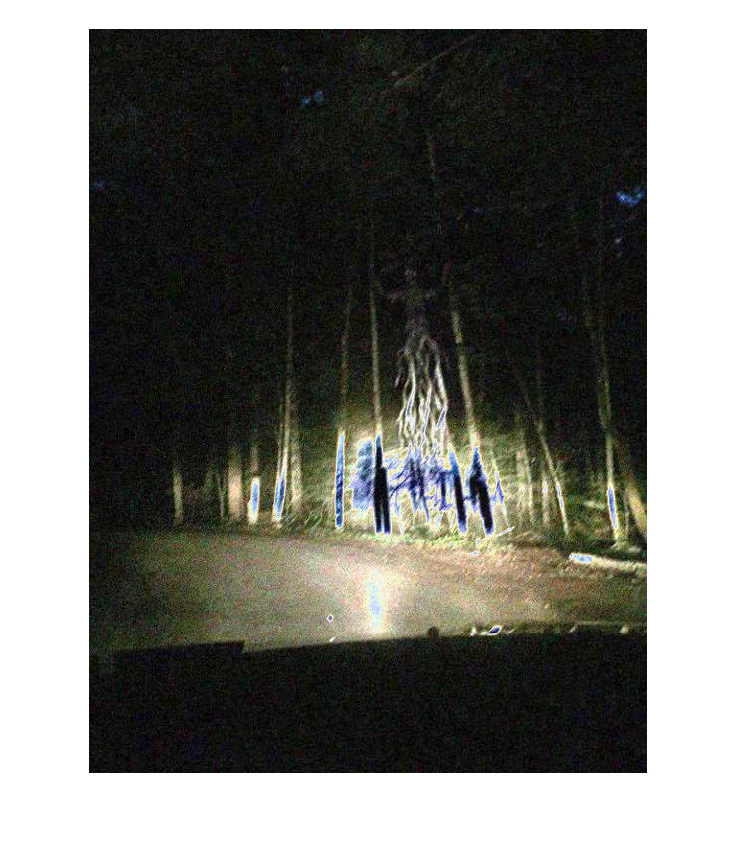

figure(2); imshow(b);

Histograma

% s = size(a)
% histag = zeros(1,256);
% histbg = zeros(1,256);
% for f = 1:s(1)
%     for c = 1:s(2)
%         ng = ag(f,c);
%         histag(ng+1) = histag(ng + 1) + 1;
%         ng = bg(f,c);
%         histbg(ng+1) = histbg(ng + 1) + 1;
%     end
% end
% figure(1);subplot(2,2,3); plot(histag); title("Hist. Imagen Original");
% figure(1);subplot(2,2,4); plot(histbg); title("Hist: Imagen Procesada");